## Wing Design

cruise = AirCondition()

cruise =   AirCondition with properties:

      M: []
      V: []
      h: []
    rho: []
      T: []
      a: []
      P: []
     nu: []
     mu: []
     Re: []


cruise.M = 0.8;
cruise.h = convlength(39000, 'ft','m');

## 1.Design CL

CLdes = W0_Sref_cruise/(1/2*cruise.rho*cruise.V^2)

Unrecognized function or variable 'W0_Sref_cruise'.

## 2.Airfoil Selection

1.Choose a t/c ratio optimum for the cruise speed

2.Choose a CLopt (at L/D max or called drag-bucket) close to design CL

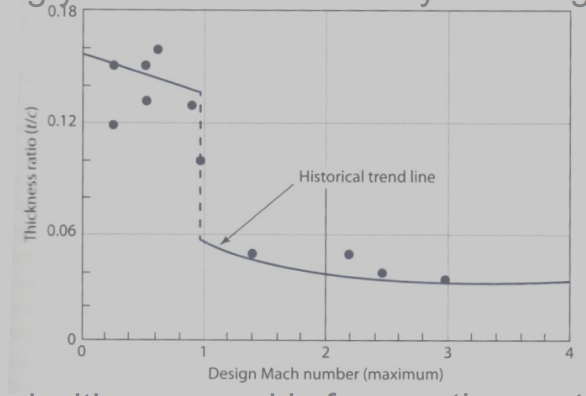

### Conclusion:

polarName = "xf-sc21010-il-1000000.csv";
shapeName = "sc21010.dat.txt";

## 3.Shape

1.Use MDO to get best geometry

    -Make sure it is applicable to double-tapered, swept wing

    -At each iteration inside MDO, calculate the optimum twist to give elliptical lift distribution

    -Use a validated wing weight estimation model

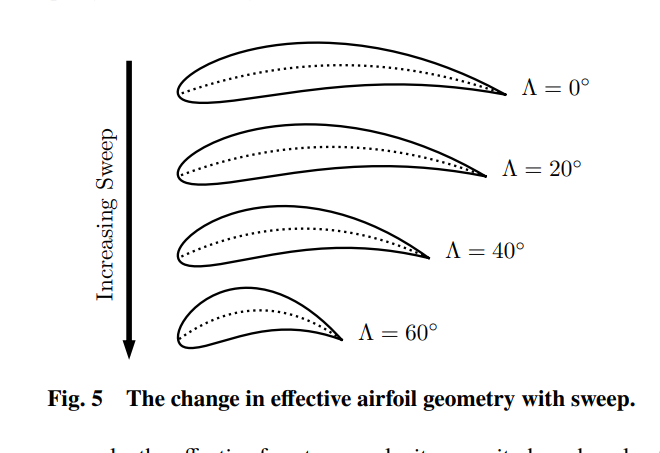

% Initial guess
x0 = [12, 8, 3, 30, 31*pi/180, 25*pi/180, 12, deg2rad(1)];
% Design variables bounds
lb = x0.*0.5;
ub = x0.*2;
wing0 = x02wing(x0);

figure;
clf;
axis equal
wing0.plotWing()
hold on
% Optimization options
options = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'sqp');
% Run the optimization
[x_opt, fval] = fmincon(@wingMDO, x0, [], [], [], [], lb, ub, @constraintFunction, options);

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7485e-07"

    "CDi = "    "0.0081241"

    "CDtotal = "    "0.019009"

    "CLclean = "    "0.69391"

L/D = 36.5052
    "Sref = "    "438"



optIndex = 1.3868e+04

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7485e-07"

    "CDi = "    "0.0081241"

    "CDtotal = "    "0.019009"

    "CLclean = "    "0.69391"

L/D = 36.5052
    "Sref = "    "438"



optIndex = 1.3868e+04

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7485e-07"

    "CDi = "    "0.0081241"

    "CDtotal = "    "0.019009"

    "CLclean = "    "0.69391"

L/D = 36.5052
    "Sref = "    "438"



optIndex = 1.3868e+04

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7485e-07"

    "CDi = "    "0.0081241"

    "CDtotal = "    "0.019009"

    "CLclean = "    "0.69391"

L/D = 36.5052
    "Sref = "    "438"



optIndex = 1.3868e+04

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7485e-07"

    "CDi = "    "0.0081241"

    "CDtotal = "    "0.019009"

    "CLclean = "    "0.69391"

L/D = 36.5052
    "Sref = "    "438"



optIndex = 1.3868e+04

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7485e-07"

    "CDi = "    "0.0081241"

    "CDtotal = "    "0.019009"

    "CLclean = "    "0.69391"

L/D = 36.5052
    "Sref = "    "438"



optIndex = 1.3868e+04

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7485e-07"

    "CDi = "    "0.0081241"

    "CDtotal = "    "0.019009"

    "CLclean = "    "0.69391"

L/D = 36.5052
    "Sref = "    "438"



optIndex = 1.3868e+04

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7485e-07"

    "CDi = "    "0.0081241"

    "CDtotal = "    "0.019009"

    "CLclean = "    "0.69391"

L/D = 36.5052
    "Sref = "    "438"



optIndex = 1.3868e+04

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7485e-07"

    "CDi = "    "0.0081241"

    "CDtotal = "    "0.019009"

    "CLclean = "    "0.69391"

L/D = 36.5052
    "Sref = "    "438"



optIndex = 1.3868e+04

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7485e-07"

    "CDi = "    "0.0081241"

    "CDtotal = "    "0.019009"

    "CLclean = "    "0.69391"

L/D = 36.5052
    "Sref = "    "438"



optIndex = 1.3868e+04

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7485e-07"

    "CDi = "    "0.0081241"

    "CDtotal = "    "0.019009"

    "CLclean = "    "0.69391"

L/D = 36.5052
    "Sref = "    "438"



optIndex = 1.3868e+04

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7485e-07"

    "CDi = "    "0.0081241"

    "CDtotal = "    "0.019009"

    "CLclean = "    "0.69391"

L/D = 36.5052
    "Sref = "    "438"



optIndex = 1.3868e+04

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7485e-07"

    "CDi = "    "0.0081241"

    "CDtotal = "    "0.019009"

    "CLclean = "    "0.69391"

L/D = 36.5052
    "Sref = "    "438"



optIndex = 1.3868e+04

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7485e-07"

    "CDi = "    "0.0081241"

    "CDtotal = "    "0.019009"

    "CLclean = "    "0.69391"

L/D = 36.5052
    "Sref = "    "438"



optIndex = 1.3868e+04

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7485e-07"

    "CDi = "    "0.0081241"

    "CDtotal = "    "0.019009"

    "CLclean = "    "0.69391"

L/D = 36.5052
    "Sref = "    "438"



optIndex = 1.3868e+04

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7485e-07"

    "CDi = "    "0.0081241"

    "CDtotal = "    "0.019009"

    "CLclean = "    "0.69391"

L/D = 36.5052
    "Sref = "    "438"



optIndex = 1.3868e+04

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7485e-07"

    "CDi = "    "0.0081241"

    "CDtotal = "    "0.019009"

    "CLclean = "    "0.69391"

L/D = 36.5052
    "Sref = "    "438"



optIndex = 1.3868e+04

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.010884"

    "CDW = "    "5.7485e-07"

    "CDi = "    "0.0081241"

    "CDtotal = "    "0.019009"

    "CLclean = "    "0.69391"

L/D = 36.5052
    "Sref = "    "438"



optIndex = 1.3868e+04

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           9    1.386822e+04     7.720e+01     1.000e+00     0.000e+00     3.454e+04  
Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009844"

    "CDW = "    "0.00052976"

    "CDi = "    "0.0060709"

    "CDtotal = "    "0.016445"

    "CLclean = "    "0.84014"

L/D = 51.0889
    "Sref = "    "498.127"



optIndex = 5.5420e+03

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009844"

    "CDW = "    "0.00052976"

    "CDi = "    "0.0060709"

    "CDtotal = "    "0.016445"

    "CLclean = "    "0.84014"

L/D = 51.0889
    "Sref = "    "498.127"



optIndex = 5.5420e+03

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009844"

    "CDW = "    "0.00052976"

    "CDi = "    "0.0060709"

    "CDtotal = "    "0.016445"

    "CLclean = "    "0.84014"

L/D = 51.0889
    "Sref = "    "498.127"



optIndex = 5.5420e+03

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009844"

    "CDW = "    "0.00052976"

    "CDi = "    "0.0060709"

    "CDtotal = "    "0.016445"

    "CLclean = "    "0.84014"

L/D = 51.0889
    "Sref = "    "498.127"



optIndex = 5.5420e+03

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009844"

    "CDW = "    "0.00052976"

    "CDi = "    "0.0060709"

    "CDtotal = "    "0.016445"

    "CLclean = "    "0.84014"

L/D = 51.0889
    "Sref = "    "498.127"



optIndex = 5.5420e+03

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009844"

    "CDW = "    "0.00052976"

    "CDi = "    "0.0060709"

    "CDtotal = "    "0.016445"

    "CLclean = "    "0.84014"

L/D = 51.0889
    "Sref = "    "498.127"



optIndex = 5.5420e+03

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009844"

    "CDW = "    "0.00052976"

    "CDi = "    "0.0060709"

    "CDtotal = "    "0.016445"

    "CLclean = "    "0.84014"

L/D = 51.0889
    "Sref = "    "498.127"



optIndex = 5.5420e+03

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009844"

    "CDW = "    "0.00052976"

    "CDi = "    "0.0060709"

    "CDtotal = "    "0.016445"

    "CLclean = "    "0.84014"

L/D = 51.0889
    "Sref = "    "498.127"



optIndex = 5.5420e+03

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009844"

    "CDW = "    "0.00052976"

    "CDi = "    "0.0060709"

    "CDtotal = "    "0.016445"

    "CLclean = "    "0.84014"

L/D = 51.0889
    "Sref = "    "498.127"



optIndex = 5.5420e+03

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009844"

    "CDW = "    "0.00052976"

    "CDi = "    "0.0060709"

    "CDtotal = "    "0.016445"

    "CLclean = "    "0.84014"

L/D = 51.0889
    "Sref = "    "498.127"



optIndex = 5.5420e+03

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009844"

    "CDW = "    "0.00052976"

    "CDi = "    "0.0060709"

    "CDtotal = "    "0.016445"

    "CLclean = "    "0.84014"

L/D = 51.0889
    "Sref = "    "498.127"



optIndex = 5.5420e+03

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009844"

    "CDW = "    "0.00052976"

    "CDi = "    "0.0060709"

    "CDtotal = "    "0.016445"

    "CLclean = "    "0.84014"

L/D = 51.0889
    "Sref = "    "498.127"



optIndex = 5.5420e+03

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009844"

    "CDW = "    "0.00052976"

    "CDi = "    "0.0060709"

    "CDtotal = "    "0.016445"

    "CLclean = "    "0.84014"

L/D = 51.0889
    "Sref = "    "498.127"



optIndex = 5.5420e+03

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009844"

    "CDW = "    "0.00052976"

    "CDi = "    "0.0060709"

    "CDtotal = "    "0.016445"

    "CLclean = "    "0.84014"

L/D = 51.0889
    "Sref = "    "498.127"



optIndex = 5.5420e+03

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009844"

    "CDW = "    "0.00052976"

    "CDi = "    "0.0060709"

    "CDtotal = "    "0.016445"

    "CLclean = "    "0.84014"

L/D = 51.0889
    "Sref = "    "498.127"



optIndex = 5.5420e+03

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009844"

    "CDW = "    "0.00052976"

    "CDi = "    "0.0060709"

    "CDtotal = "    "0.016445"

    "CLclean = "    "0.84014"

L/D = 51.0889
    "Sref = "    "498.127"



optIndex = 5.5420e+03

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009844"

    "CDW = "    "0.00052976"

    "CDi = "    "0.0060709"

    "CDtotal = "    "0.016445"

    "CLclean = "    "0.84014"

L/D = 51.0889
    "Sref = "    "498.127"



optIndex = 5.5420e+03

Process is complete! Converged circulation distribution found.
    "CDF = "    "0.009844"

    "CDW = "    "0.00052976"

    "CDi = "    "0.0060709"

    "CDtotal = "    "0.016445"

    "CLclean = "    "0.84014"

L/D = 51.0889
    "Sref = "    "498.127"



optIndex = 5.5420e+03

    1          18    5.541998e+03     1.707e+01     1.000e+00     4.952e+00     5.220e+01  


wing_opt = x02wing(x_opt);
figure(1)
clf;
wing_opt.plotWing()


## 4.Dihedral

-G17 presents a quantitative estimate

## 5.HLD

1.Calculate CLmax requirement at landing and takeoff

2.Select

## 6.Control Surfaces

## 7.Tailplane design

## 8.Nose shape optimization